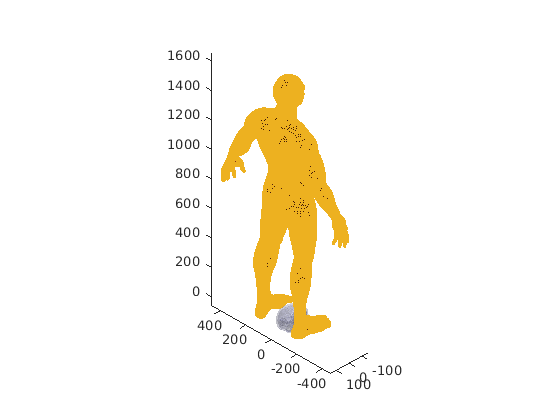

%Options
skin1 = 'FacColor';

skin2 = [0.9290 0.6940 0.1250];
skull_color_2=[0 0 0.7];
skull_color_1=[1 1 1];
skul_height=3;

N=112;
height_img= round(skul_height/N,2);
[V,F,UV,TF,N,NF] = readOBJ('Human_body.obj');
p = patch('faces',F,'vertices',V,'FaceColor',skin1,'EdgeColor',skin2);
%Rotate
alpha=pi/2;
R=rotx(alpha);
V2=V2*R;

%Ficudals

Ficudal1=Ficudal1*R;
Ficudal2=Ficudal2*R;
Ficudal3=Ficudal3*R;

%Translate
T= transl(0,6,0);

t1 = [Ficudal1 1]';
tt1 = T*t1;
Ficudal1 = tt1(1:3);

for i=1:size(V2,1)
    for j=1:size(V2,2)
            aux = [V2(i,:) 1]';
            P = T*aux;
            V2(i,:) = P(1:3);
    end
end


Ficudal1=Ficudal1';
Ficudal2=Ficudal2';
Ficudal3=Ficudal3';

%Display
figure
axis ([-10 10 -5 25 -2 20])

h2=fill3(X_table,Y_table,Z_table,[0.7 0.3 0]);
hold on

hold on
p2 = patch('faces',F2,'vertices',V2,'FaceColor',skull_color_1,'EdgeColor',skull_color_2);
hold on
%surf(0.015*x+Ficudal1(1,1),0.015*y+Ficudal1(2,1),0.015*z+Ficudal1(3,1));

hold on
%surf(0.015*x2+Ficudal2(1,1),0.015*y2+Ficudal2(2,1),0.015*z2+Ficudal2(3,1));

hold on
%surf(0.015*x3+Ficudal3(1,1),0.015*y3+Ficudal3(2,1),0.015*z3+Ficudal3(3,1));
